% Load class names
load("D:\0 - Downloads\Chrome\Matlab\Keras\traffic_sign_class_names.mat")
class_names = cellstr(class_names)

class_names = 10×1 cell array
    {'No_Parking'                    }
    {'No_Parking_Damaged'            }
    {'Parking'                       }
    {'Parking_Damaged'               }
    {'Road_Construction_Sign'        }
    {'Road_Construction_Sign_Damaged'}
    {'Stop'                          }
    {'Stop-Damaged'                  }
    {'Zebra_Crossing'                }
    {'Zebra_Crossing_Damaged'        }



% Load model
% imageSize = [224 224 3];
% model = importKerasNetwork("D:\0 - Downloads\Chrome\Matlab\Keras\traffic_sign_classifier_A_resnet50.h5",'ImageInputSize',imageSize);

% Prompt user to select an image file
[fileName, filePath] = uigetfile({'*.png;*.jpg;*.jpeg', 'Image Files (*.png,*.jpg,*.jpeg)'}, 'Select an image file');
if fileName == 0
    disp('No file selected. Exiting.');
    return;
end

% Load and preprocess selected image
imgPath = fullfile(filePath, fileName);
img = imread(imgPath);
img = imresize(img, [224 224]);  % Resize input image to [224 224]

% Predict
pred = predict(model, img);

% Find the class with the maximum predicted probability
[maxProb, maxIdx] = max(pred);

% Convert index to class name using class_names
if maxIdx >= 1 && maxIdx <= numel(class_names)
    className = class_names(maxIdx);
else
    className = 'Unknown Class';
end

% Display results
fprintf('Predicted class: %s (Probability: %.2f)\n', className{1}, maxProb);

Predicted class: Zebra_Crossing (Probability: 0.99)


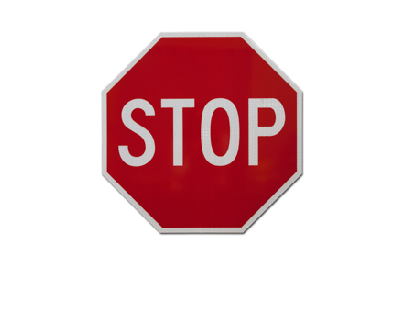

imshow(img);  % Display the selected image